# **META 4**

21. Carregue a estrutura de dados guardada no último ponto da meta anterior.

dados = load("dados.mat").dados;

tabela = struct2table(dados); 
disp(tabela);

          diretorio            nomeFicheiro      participante    digito    repeticao         sinal          taxaAmostragem    tamanhoSinal    fimAudio    taxaCruzamentoZeros    energiaTotal    tAmplitudeMaxima    razaoAmplitude    desvioPadrao    coeficientesFourier    frequenciaDominante     par      entropia     sef      spectralSlope    specMeanFreq    specMaxFreq    specBandwidth    specEntropy    specEnergy                 energia_dwt              
    ______________________    _______________    _________

22. Calcule, para cada dígito, a STFT, como exemplificado na Figura 5. Use diferentes parametrizações, por exemplo tamanho da janela, sobreposição, número de pontos para cálculo da FFT, etc., e identifique os parâmetros que lhe parecem mais adequados para o objetivo do trabalho. Comente as observações. Nota: utilize a função spectrogram do MATLAB (consulte a documentação associada).

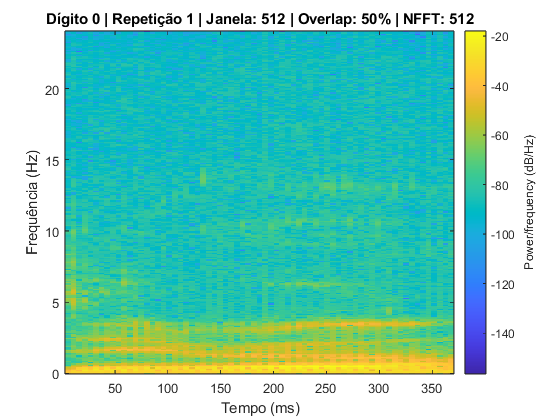

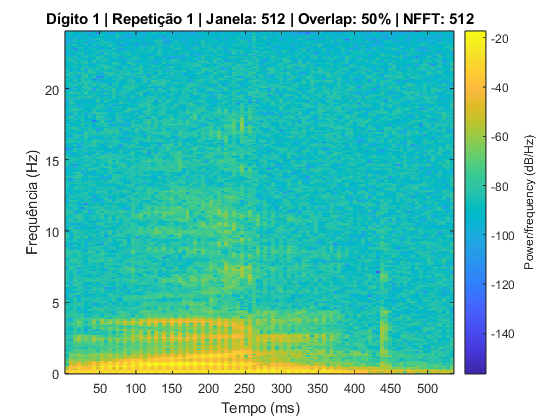

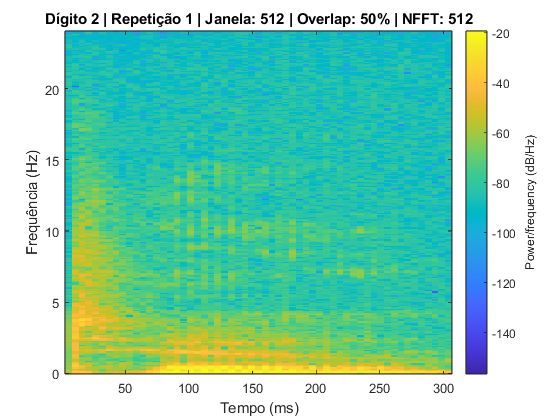

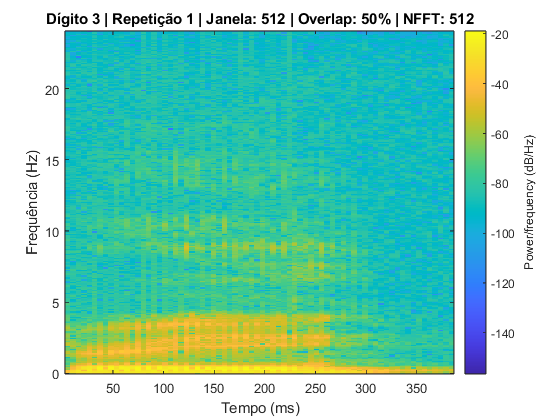

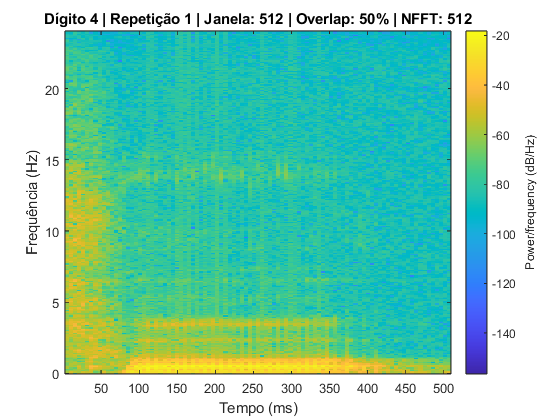

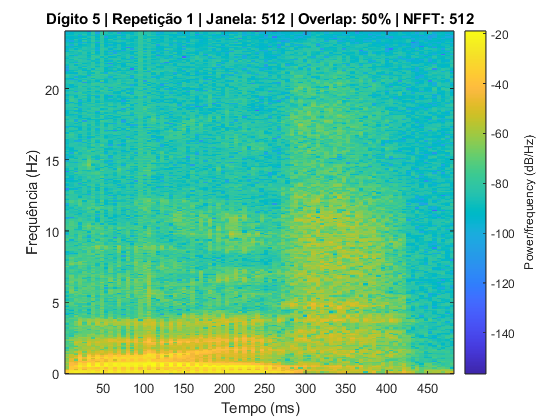

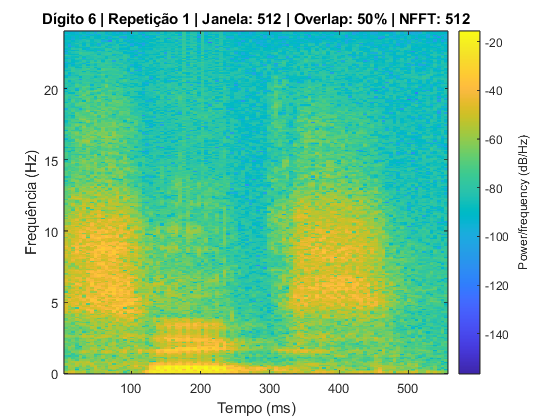

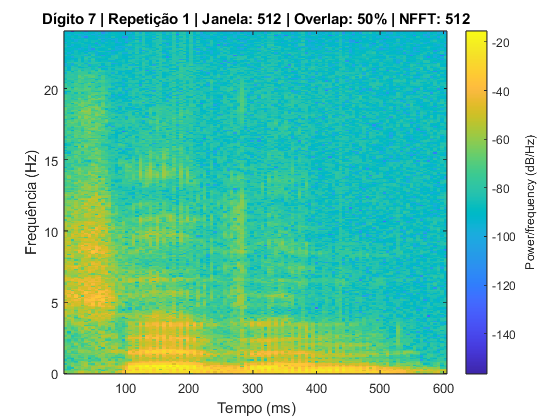

taxaAmostragem = 48000;
tamanhoJanela = 512; 
overlap = 0.5; 
numFFT = 512;
repeticao = 1; 

for digito = 0:9
    indice = find([dados.digito] == digito & [dados.repeticao] == repeticao, 1, 'first');
    if isempty(indice)
        continue;
    end
    sinal = dados(indice).sinal;
    fimAudio = dados(indice).fimAudio;
    sinal = sinal(1:fimAudio); % Só até ao fim do áudio real
    numOverlap = round(tamanhoJanela * overlap);
    figure;
    spectrogram(sinal, tamanhoJanela, numOverlap, numFFT, taxaAmostragem, 'yaxis');
    xlabel('Tempo (ms)');
    ylabel('Frequência (Hz)');
    title(['Dígito ', num2str(digito), ' | Repetição ', num2str(repeticao), ...
        ' | Janela: ', num2str(tamanhoJanela), ' | Overlap: ', num2str(overlap*100), '% | NFFT: ', num2str(numFFT)]);
end

23. Extraia pelo menos 5 características de tempo-frequência em diferentes janelas tempo-frequência que possam ser mais relevantes para a diferenciação dos dígitos. Deverá atualizar a sua estrutura de dados.

for i = 1:length(dados)
    sinal = dados(i).sinal;
    [s,f,t,p] = spectrogram(sinal, tamanhoJanela, numOverlap, numFFT, taxaAmostragem);
    p = abs(p).^2;
    meanP = mean(p,2); % Média da potência por frequência
    
    % 1. Frequência média (weighted mean)
    dados(i).specMeanFreq = sum(f .* meanP) / sum(meanP);
    
    % 2. Frequência máxima (frequência com maior energia média)
    [~, idxMax] = max(meanP);
    dados(i).specMaxFreq = f(idxMax);
    
    % 3. Largura de banda (desvio padrão da distribuição de energia)
    dados(i).specBandwidth = sqrt(sum(((f - dados(i).specMeanFreq).^2) .* meanP) / sum(meanP));
    % 4. Entropia espectral
    
    p_norm = meanP / sum(meanP);
    dados(i).specEntropy = -sum(p_norm .* log(p_norm + eps));
    % 5. Energia total
    
    dados(i).specEnergy = sum(p(:));
end

24. Recorrendo à representação gráfica das características tempo-frequência extraídas no ponto anterior, identifique as três características que permitem uma melhor discriminação dos dígitos. Para isto pode utilizar boxplots, gráficos 2D, 3D, etc. Indique as características escolhidas.

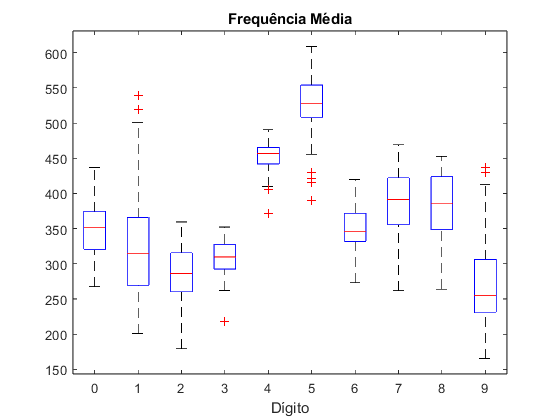

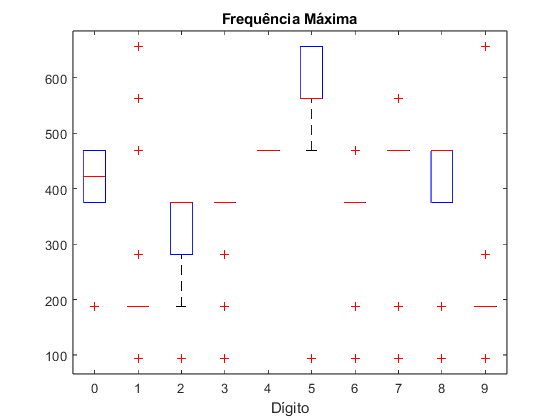

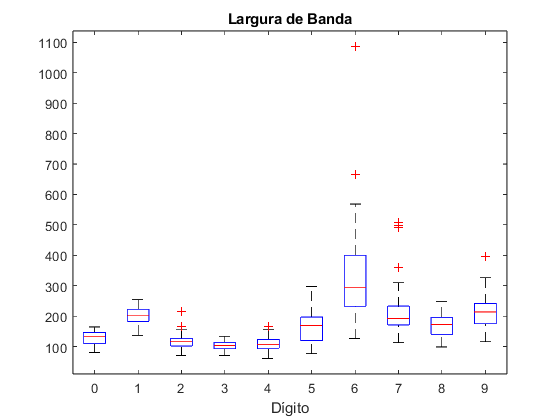

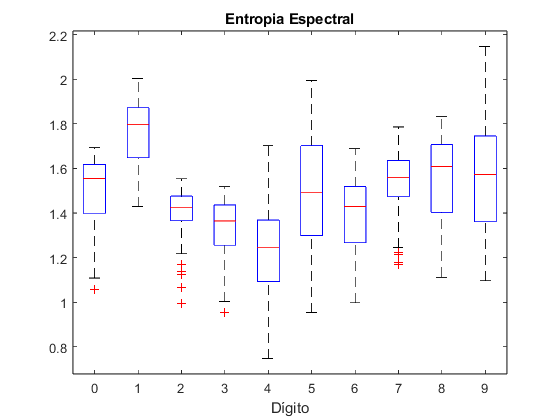

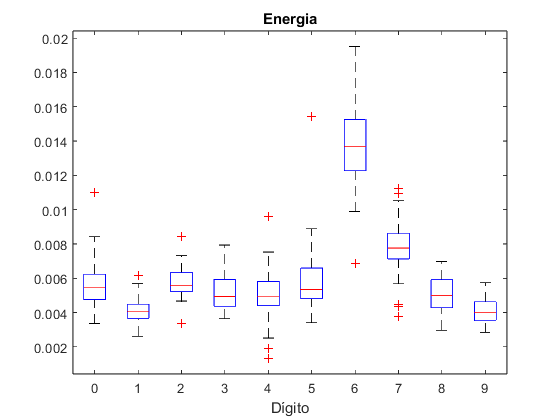

digitos = [dados.digito]';
features = [[dados.specMeanFreq]', [dados.specMaxFreq]', [dados.specBandwidth]', ...
            [dados.specEntropy]', [dados.specEnergy]'];

feature_names = {'Frequência Média', 'Frequência Máxima', ...
                 'Largura de Banda', 'Entropia Espectral', 'Energia'};

for i = 1:5
    figure;
    boxplot(features(:,i), digitos);
    title(feature_names{i});
    xlabel('Dígito');
end

25. Aplicar a Transformada de Wavelet Discreta (DWT) para obter os coeficientes de detalhe e de aproximação, utilizando um nível de decomposição e o tipo de wavelet que considere apropriado. Obter os valores de energia a partir dos coeficientes e representar os resultados, utilizando gráficos semelhantes aos exemplificados na Figura 3. Compare e discuta os resultados obtidos com a STFT e com a DWT.

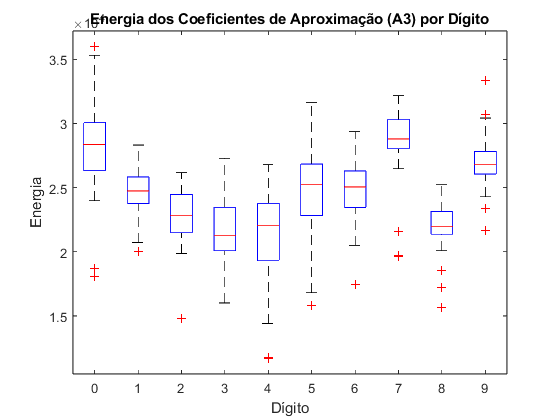

onda = 'db4'; % Escolha da wavelet (pode ser alterada)
nivel = 3;    % Nível de decomposição (ajuste conforme necessário)

for i = 1:length(dados)
    sinal = dados(i).sinal;
    [C, L] = wavedec(sinal, nivel, onda);
    
    % Coeficientes de aproximação no último nível
    cA = appcoef(C, L, onda, nivel);
    
    % Coeficientes de detalhe em cada nível
    cD1 = detcoef(C, L, 1);
    cD2 = detcoef(C, L, 2);
    cD3 = detcoef(C, L, 3);

    % Energia dos coeficientes
    dados(i).dwtEnergyA = sum(cA.^2);
    dados(i).dwtEnergyD1 = sum(cD1.^2);
    dados(i).dwtEnergyD2 = sum(cD2.^2);
    dados(i).dwtEnergyD3 = sum(cD3.^2);
end

% Boxplots das energias por dígito
digitos = [dados.digito]';
energiesA = [dados.dwtEnergyA]';
energiesD1 = [dados.dwtEnergyD1]';
energiesD2 = [dados.dwtEnergyD2]';
energiesD3 = [dados.dwtEnergyD3]';

figure;
boxplot(energiesA, digitos);
title('Energia dos Coeficientes de Aproximação (A3) por Dígito');
xlabel('Dígito');
ylabel('Energia');

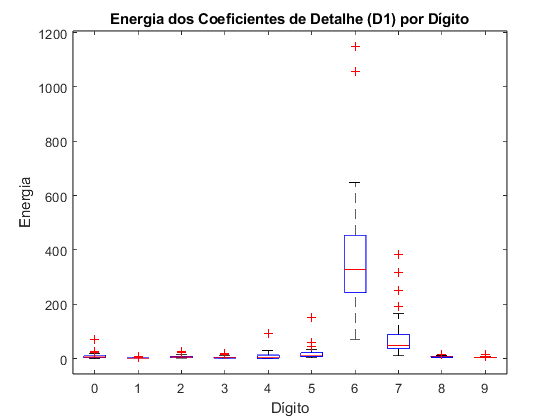


figure;
boxplot(energiesD1, digitos);
title('Energia dos Coeficientes de Detalhe (D1) por Dígito');
xlabel('Dígito');
ylabel('Energia');

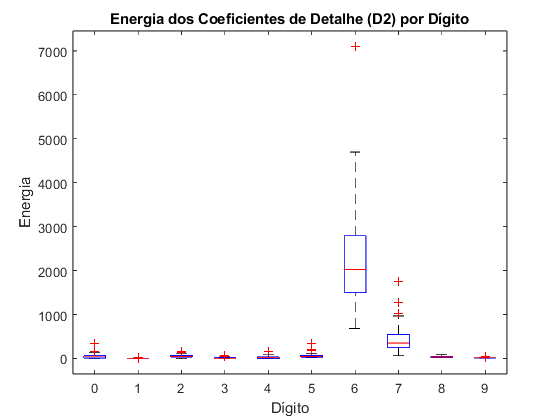


figure;
boxplot(energiesD2, digitos);
title('Energia dos Coeficientes de Detalhe (D2) por Dígito');
xlabel('Dígito');
ylabel('Energia');

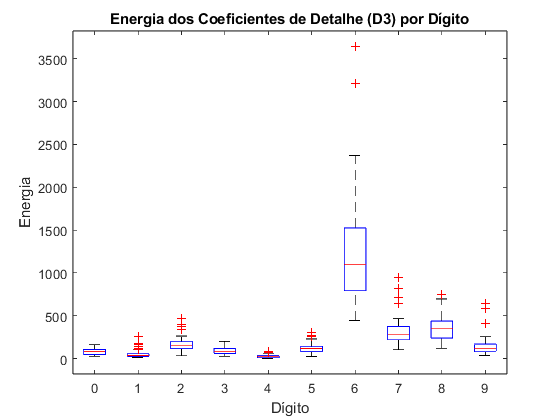


figure;
boxplot(energiesD3, digitos);
title('Energia dos Coeficientes de Detalhe (D3) por Dígito');
xlabel('Dígito');
ylabel('Energia');

26. Atualize o ficheiro “.mat” carregado no início da meta com a estrutura de dados atualizada.

save('dados.mat', 'dados');